## using rigid body tree cell to make a mdh dhparameters rigid body with 3 bodies

Using a circle path trajectory (so that the velocity is also continous) in work space, starting point on the radius that is pre-assigned, no need to move to the circle. Using sin/cos and directly the inverse kinematics to pre-assign the location!

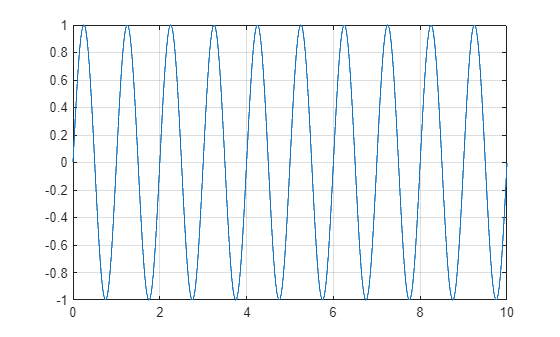

clc;
% clear all;
close all;

% New z-planar mDH table using craig's example, for a 2-link robot.
t =linspace(0,10,10001);    % total simulation of 10 seconds, SR 1000 hz, ST 1ms.

f = 1;      % 1 hz (one cycle per second, 1 rps = 60 rpm) likly 10 revolutions

v = sin(2*pi*f*t);   % set velocity at 10 cm/s, so it is a constant velocity using sine

fig1 = figure('Name',"Velocity assigment");
ax1 = axes('Parent', fig1);

plot(ax1, t, v);
grid(ax1, 'on');

## Assigning frames first with mdh in mind

make and show base frame

assign base frame, so to later affix joint frame 1


% using standard frame with original location and standard orientation,
% plot on base figure
eul = [0 0 0]

eul =      0     0     0


xyz = [0 0 0]

xyz =      0     0     0



eul2tform(eul)  % check tranformation and representations

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


eul2rotm(eul)   % check rotational matrix representations 

ans =      1     0     0
     0     1     0
     0     0     1


eul2quat(eul)   % quaternion representation. remember quaternion is so3

ans =      1     0     0     0



trvec2tform(xyz)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



tt = trvec2tform(xyz)*eul2tform(eul)

tt =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



fig2 = figure('Name',"Add frame slowly");
ax2 = axes('Parent',fig2);
hold(ax2, 'on');
grid(ax2, 'on');
axis(ax2, 'equal');

plotTransforms(tform2trvec(tt),tform2quat(tt), 'Parent', ax2);  % base frame no bodies added!!!


### 1nd frame

%% moving to next frame manually...
eul = [0 0 pi/2];   % turn about z-axis to 45 degrees
xyz = [0 0 1.5];      % move along z-axis to point plus one
quat = eul2quat(eul);   % change euler representation into quaternion representation

tt = tt*trvec2tform(xyz)*quat2tform(quat);  % change (homogeneous multiplication transform) to full se3 matrix

plotTransforms(xyz, tform2quat(tt), 'Parent', ax2);     % first frame moved up, use above transfomation
                                                    % NOTE!! tt pre-multiplications!! 

### 2rd frame

% 2nd move to next frame
eul = [0 0 0];
xyz = [0 0 1.5];
quat = eul2quat(eul);

tt = tt*trvec2tform(xyz)*quat2tform(quat)   % moved based on most recent moved tt transform, note tt *=

tt =     1.0000         0         0         0
         0    0.0000   -1.0000   -1.5000
         0    1.0000    0.0000    1.5000
         0         0         0    1.0000



plotTransforms(tform2trvec(tt), tform2quat(tt), 'Parent', ax2);


### 3rd frame

% 3rd move to frame
eul = [0 0 0];
xyz = [0 0 1.5];
quat = eul2quat(eul);

tt = tt*trvec2tform(xyz)*quat2tform(quat)   % moved based on most recent moved tt transform, note tt *=

tt =     1.0000         0         0         0
         0    0.0000   -1.0000   -3.0000
         0    1.0000    0.0000    1.5000
         0         0         0    1.0000


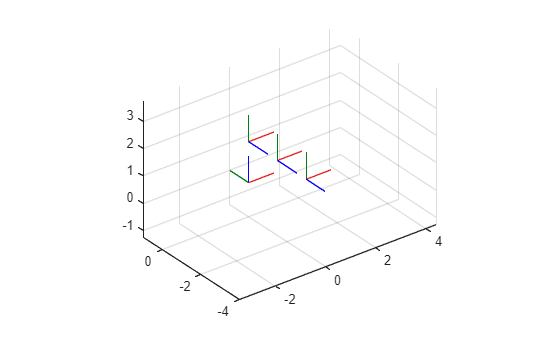


plotTransforms(tform2trvec(tt), tform2quat(tt), 'Parent', ax2);

## Try with using mdh parameter

making the mdh table

but still needs to be total se3 object 

% make sure rigid body cell names and joints are named
bodies = cell(1,3);
joints = cell(1,3);
jtype = {"revolute","revolute","fixed"};

twolink_robot = rigidBodyTree('DataFormat','column','MaxNumBodies',3);

[nrow, ncol] = size(bodies);

for i = 1:ncol
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],jtype{i});
end

% with a_1 = 0.5, a_2 = 0.5;
% using theta_1 = pi/3 (param);, theta_2 = pi/4 (param); theta_3 = 0 (fixed);
th1 = pi/7;
th2 = pi/9;
a1 = 0.5;
a2 = 0.5;
th3 = 0;

mdh_param = [0 0 0 th1; a1 0 0 th2; a2 0 0 th3]

mdh_param =          0         0         0    0.4488
    0.5000         0         0    0.3491
    0.5000         0         0         0


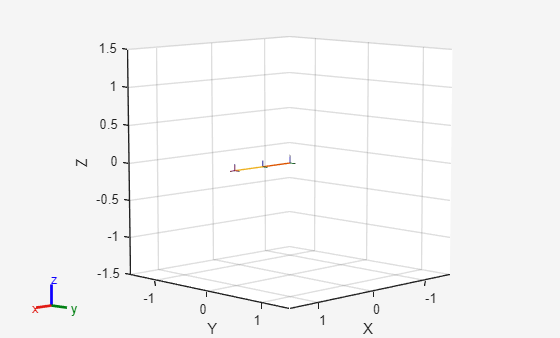


for i = 1:3

    setFixedTransform(joints{i}, mdh_param(i,:),'mdh');
    bodies{i}.Joint = joints{i};

    if i == 1
        addBody(twolink_robot,bodies{i},"base")
    else
        addBody(twolink_robot,bodies{i},bodies{i-1}.Name)
    end
end

fig3 = figure('Name',"2-link Planar Upright Robot");
ax3 = axes('Parent', fig3);
show(twolink_robot, 'Parent', ax3);


% getJointFrames(twolink_robot)